Question 1

k_val = linspace(-5, 20, 400); % More refined k range
final_states_x = zeros(length(k_val), 1); % Collect final x values for plotting
final_states_y = zeros(length(k_val), 1); % Collect final y values for plotting
init_val_of_x_and_y = [-1 1]

init_val_of_x_and_y =     -1     1


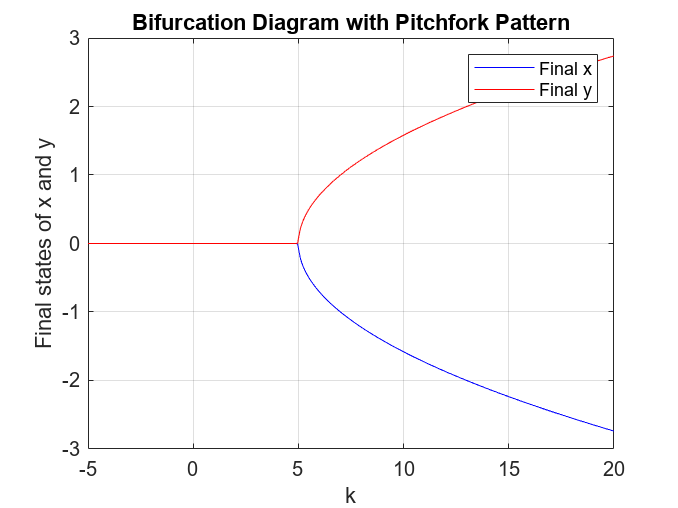


options = odeset('RelTol',1e-6,'AbsTol',1e-9); % Solver precision

for i = 1:length(k_val)
    k = k_val(i);
    % Solve for positive initial conditions
    [t, sol] = ode45(@(t, x) oscSys(t, x, k), [0 100], init_val_of_x_and_y, options);
    final_states_x(i) = sol(end, 1);
    final_states_y(i) = sol(end, 2);

end

figure;
plot(k_val, final_states_x, 'b-');
hold on;
plot(k_val, final_states_y, 'r-');
xlabel('k');
ylabel('Final states of x and y');
title('Bifurcation Diagram with Pitchfork Pattern');
legend('Final x', 'Final y');
grid on;
hold off;

WIth the intial x value being negative 1, the bifurcation has a pitchfork in the negative while the initial y value being positive 1, the bifurcation has a pitchfork in the positive. This graph together makes a pitchfork bifurcation across values of k.

Question 2

% Parameters
mu = 10; % large mu for relaxation oscillation
tspan = [0 100]; % time span for the simulation

% Initial conditions
y0 = [2; 0]; % Initial condition [x0; y0]

% Solve the system using ode45
[time, sol] = ode45(@(t, y) vanderPolModified(t, y, mu), tspan, y0);

% Plot the nullclines and the trajectory
figure;
hold on;
% Nullclines
fplot(@(x) (1/3)*x^3 - x, [-3 3], 'b--', 'LineWidth', 2); % y nullcline x^3/3 - x

fplot(@(x) 0,  [-3 3], 'r--', 'LineWidth', 2); % x nullcline

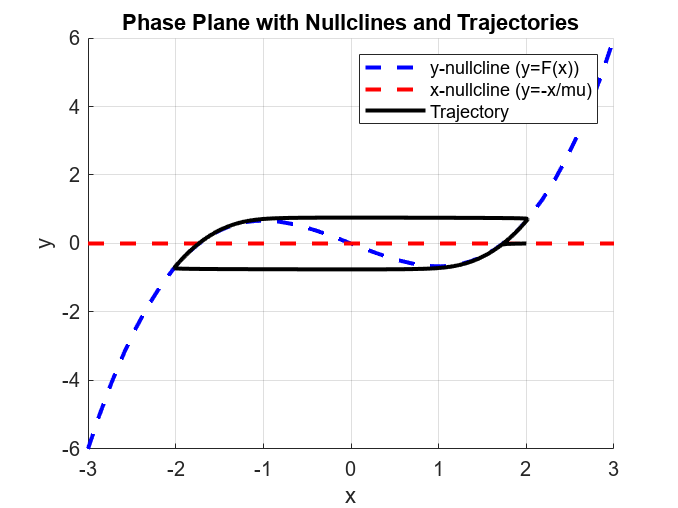

% Trajectory
plot(sol(:,1), sol(:,2), 'k', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Phase Plane with Nullclines and Trajectories');
legend('y-nullcline (y=F(x))', 'x-nullcline (y=-x/mu)', 'Trajectory');
grid on;

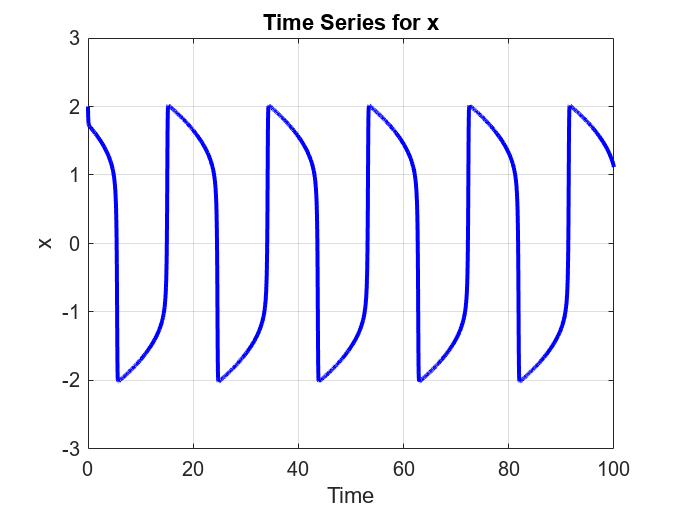


% Plot x vs time
figure;
plot(time, sol(:,1), 'b-', 'LineWidth', 2);
xlabel('Time');
ylabel('x');
title('Time Series for x');
grid on;

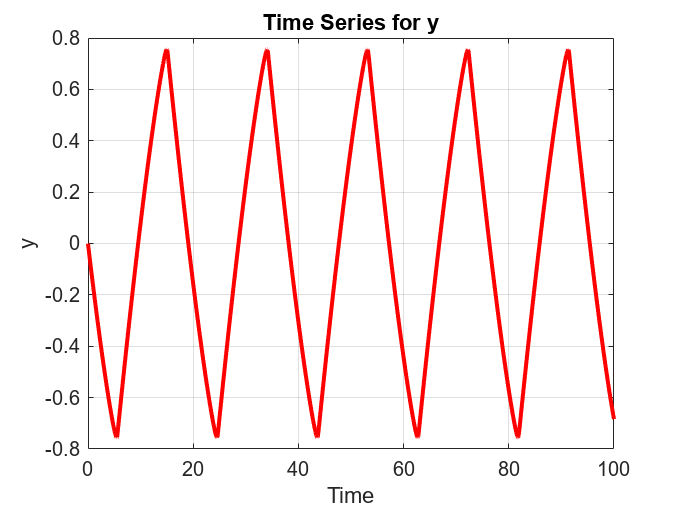


% Optionally, plot y vs time
figure;
plot(time, sol(:,2), 'r-', 'LineWidth', 2);
xlabel('Time');
ylabel('y');
title('Time Series for y');
grid on;

hold off;

The trajectory makes a weird circular path along the y-nullcline curve and is parallel to the x-nullcline. The two x and y vs time graphs have different types of oscillations, showing that they are different time scales. 

function dxdt = oscSys(t, x, k)
    dxdt = zeros(2,1); % Since we have two equations
    dxdt(1) = k*x(1) + 5*x(2) - x(1)*(x(1)^2 + x(2)^2); % x'
    dxdt(2) = 5*x(1) + k*x(2) - x(2)*(x(1)^2 + x(2)^2); % y'
end

% Define the system of differential equations
function dy = vanderPolModified(t, y, mu)
    dy = zeros(2,1);
    dy(1) = mu * (y(2) - ((1/3)*y(1)^3 - y(1))); % x'
    dy(2) = -y(1) / mu; % y'
end